# Main script

Within this file, everything you need to find and evaluate your magnetic field can be found! Make sure to modify values where it's suggested, and to only run the blocks you need!

## Determine magnetic moment of dipoles

Simulate the magnetic field which arises from a collection of ideal magnetic dipoles, and determine how their magnetization should be set to achieve a target magnetic profile.

### Set general parameters

%% Here, specify where all dipoles and rings are located. These position must me
% explicitly specified. Each row corresponds to a dipole, and its columns
% are x, y and z positions.
OUTER_RADIUS = 0.025;

dipole_positions = [0 1 -1; 0 -1 1] * 0.025;
ring_positions = [0 0 0] * 0.027;
ring_normals = [0 -1/sqrt(2) 1/sqrt(2)];
ring_radii = [0.03*sqrt(2)];

% Now, for each dipole, and for each ring, specify its magnetic moment. Every row should
% relate to the magnetic moment of the dipole of the same row in
% 'dipole_positions'. Set values to 'nan' to indicate that the values
% should be determined by a target field.
Md_x = [0 1 1; 0 2 2];
Md_k = [0 1 -1; 0 1 -1];
Md_m = zeros(size(Md_x));

% These values go for the rings. Only axial magnetization is supported
Mr_x = [1];
Mr_k = [1];
Mr_m = zeros(size(Mr_x));

% Here, specify on which domain to evaluate the B-field. Currently, only
% discs normal to the z-axis are available
target_domain = graphene([0, 0, 0], 0.01, pi/4, 0, 0, 0);

% Finally, specify the target magnetic field profile. Any undetermined dipole
% magnetizations will be set to approximate this field, on a 2D-domain
% defined above.
target_field = B_field_quadratic_profile(target_domain, 0.1, 3, 0);

Alternatively, load parameters from file (comment this line if you want to keep settings from above):

load uniform_pp5.mat

### Set computational parameters

These parameters only affect the computational accuracy, not the problem statement

% DEN HÄR ANVÄNDS INTE I NULÄGET collision_threshold = 0.01;
xx = linspace(0, 1, 1000);
maxB = 1.3;

### Compute stuff

Now, let the magic happen! 

%% Check if any dipole is situated exactly in the evaluation area
dipole_in_domain = false;

% Use line below (but fix it plz) if you're really worried about this
% any(dipole_positions(:, 3) == target_domain.Z)

% threshold = collision_threshold * dipole_in_domain;

% Create function from degrees-of-freedom to magnetization:
nd = length(unique(Md_x))-any(Md_x == 0, 'all');
nr = length(unique(Mr_x))-any(Mr_x == 0, 'all'); % Number of free parameters

get_Md = @(x) insert_params(x(1:nd), Md_x, Md_k, Md_m);
get_Mr = @(x) insert_params(x(nd+1:end), Mr_x, Mr_k, Mr_m);

% Create function handle which returns a B-field computator B(X, Y, Z) from
% parameters x
f1 = @(x) integral(@(phi) 1./(1-x.*cos(phi)).^(5/2), 0, pi);
f2 = @(x) integral(@(phi) cos(phi)./(1-x.*cos(phi)).^(5/2), 0, pi);
F1 = arrayfun(f1, xx);

F2 = arrayfun(f2, xx);

B_func_from_x = @(x) B_function(@(xvar, X, Y, Z) get_field_with_rings(X, Y, Z, dipole_positions, ring_positions, ring_normals, ring_radii, get_Md(xvar), get_Mr(xvar), xx, F1, F2), x);

% Create a reference field computator handle B_0(X, Y, Z)
B_0 = B_function(@(~, X, Y, Z) target_field(X, Y, Z));

% Create an inner product evaluator, with information about evaluation
% domain.
inprod = inner_product(target_domain.R, target_domain.Origin, target_domain.Phi);

% GO!!!
[x, B_best] = granny_smith(B_func_from_x, B_0, inprod, nd+nr);

B_fel = @(X, Y, Z) B_best(X, Y, Z) - B_0(X, Y, Z);
error = inprod(B_fel, B_fel) / inprod(B_0, B_0)

error = 1.1816e-05

### Evaluate resulting magnetisations

p = '3';

if height(dipole_positions > 0)
    dm = sqrt(sum(get_Md(x).^2, 2)); % Magnetic dipole moment, Am^2
    dV = 4e-7*pi*dm / maxB *1e9; % Volume, mm^3
    disp('Dipole magnetic moment:')
    disp([num2str(dm, ['%-5.' p 'f']) repmat(' Am^2', height(dm), 1)])
    disp('Corresponding minimal volume:')
    disp([num2str(dV, ['%-5.' p 'f']) repmat(' mm^3', height(dm), 1)])
    disp('')
    disp('Suggested sizes:')
    disp([repmat('Height: ', height(dm), 1), num2str((3*dV/pi).^(1/3), ['%-5.' p 'f']), ...
        repmat(' mm, Radius: ', height(dm), 1), num2str((dV.^2/(pi^2*3)).^(1/6), ['%-5.' p 'f']), ...
        repmat(' mm.',  height(dm), 1)]);
end

Dipole magnetic moment:


13.920 Am^2
13.920 Am^2


Corresponding minimal volume:


13456.068 mm^3
13456.068 mm^3


Suggested sizes:


Height: 23.422 mm, Radius: 13.523 mm.
Height: 23.422 mm, Radius: 13.523 mm.


if height(ring_positions > 0)
    rm = abs(get_Mr(x));
    rV = 4e-7*pi*rm / maxB *1e9;
    rh = sqrt(rV./(2*pi*ring_radii*1000));
    disp('Ring magnetic moment:')
    disp([num2str(rm, ['%-5.' p 'f']) repmat(' Am^2', height(rm), 1)])
    disp('Corresponding minimal volume:')
    disp([num2str(rV, ['%-5.' p 'f']) repmat(' mm^3', height(rm), 1)])
    disp('')
    disp('Suggested sizes:')
    disp([repmat('Height: ', height(rm), 1), num2str(rh, ['%-5.' p 'f']), ...
        repmat(' mm, Inner radius: ', height(rm), 1), num2str(1000*ring_radii - rh/2, ['%-5.' p 'f']), ...
        repmat(' mm, Outer radius: ',  height(rm), 1), num2str(1000*ring_radii + rh/2, ['%-5.' p 'f']), ...
        repmat(' mm.',  height(rm), 1)]);
end

Ring magnetic moment:


17.091 Am^2


Corresponding minimal volume:


16521.310 mm^3


Suggested sizes:


Height: 9.642 mm, Inner radius: 23.463 mm, Outer radius: 33.105 mm.


### Plotting the result

Quiver plot

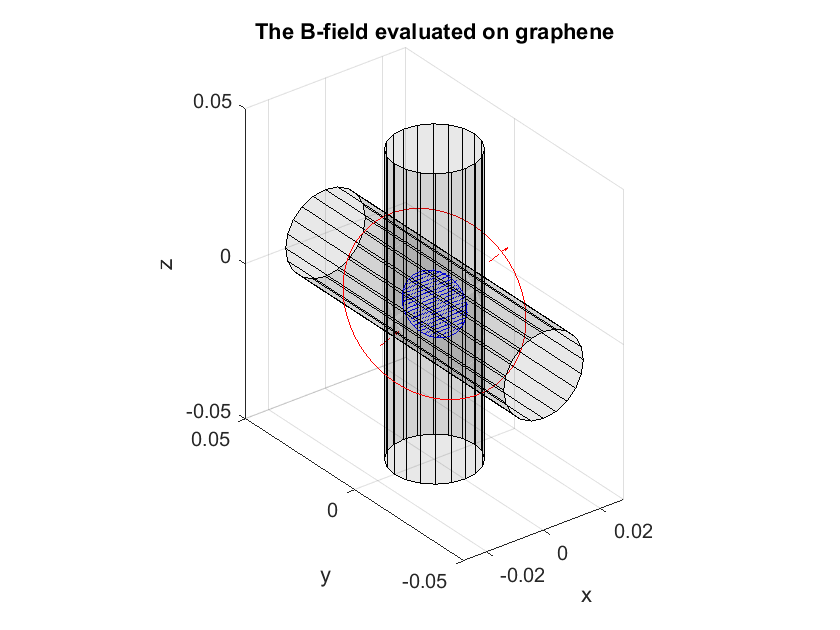

%% Select the amount of discretization points along  the diameter
N = 20;
% Create the mesh
[X,Y,Z] = meshgrid(linspace(-target_domain.R,target_domain.R,N),...
    linspace(--target_domain.R,-target_domain.R,N),0);

i = X.^2 + Y.^2 <= target_domain.R^2;

[X, Y, Z] = target_domain.Transform(X, Y, Z);

% Assigns the B-field and shows the quiver plot
B = B_best(X,Y,Z);

Bx = squeeze(B(:,:,1));
By = squeeze(B(:,:,2));
Bz = squeeze(B(:,:,3));

m = get_Md(x);

b_plot(X(i), Y(i), Z(i) ,Bx(i), By(i), Bz(i), dipole_positions, m, target_domain, ring_positions, ring_radii, ring_normals, true)


b_field_at_origo = reshape(B_best(target_domain.Origin(1),target_domain.Origin(2),target_domain.Origin(3)), [1,3]);
b_field_at_edge = reshape(B_best(target_domain.Origin(1)+target_domain.R,target_domain.Origin(2),target_domain.Origin(3)), [1,3]);
b_str_at_origo = dot(target_domain.Normal, b_field_at_origo);
b_str_at_edge = dot(target_domain.Normal, b_field_at_edge);
b_uniformity = b_str_at_edge/b_str_at_origo;

Surface plot, normal direction

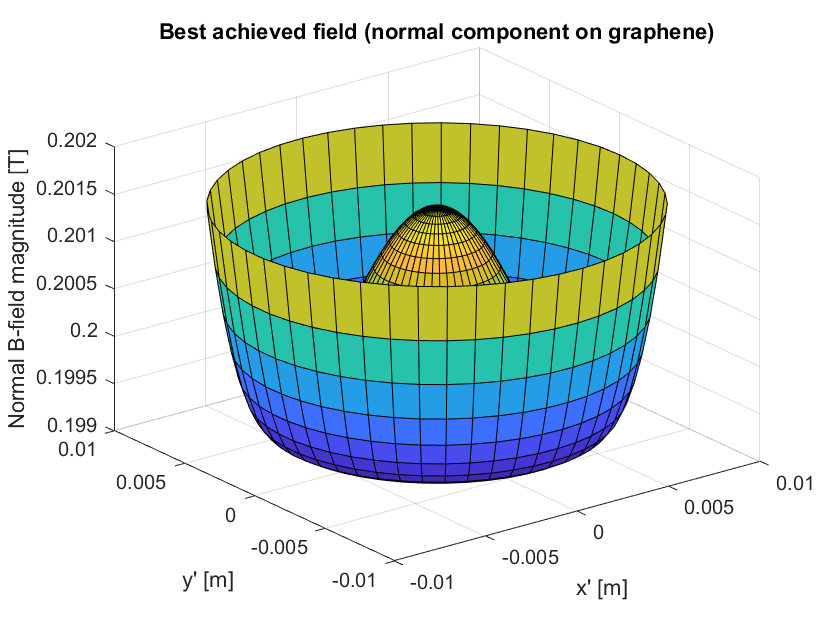

[R, T, Z] = meshgrid(linspace(0, target_domain.R, 30), linspace(0, 2*pi, 50), 0);
Xl = R.*cos(T);
Yl = R.*sin(T);
[X, Y, Z] = target_domain.Transform(Xl, Yl, Z);
B = B_best(X, Y, Z);
B0 = B_0(X, Y, Z);
n = permute(target_domain.Normal, [1 3 2]);
Bn = sum(B .* n, 3);
B0n = sum(B0 .* n, 3);
surf(Xl, Yl, Bn);
xlabel("x' [m]")
ylabel("y' [m]")
zlabel('Normal B-field magnitude [T]')
title('Best achieved field (normal component on graphene)')

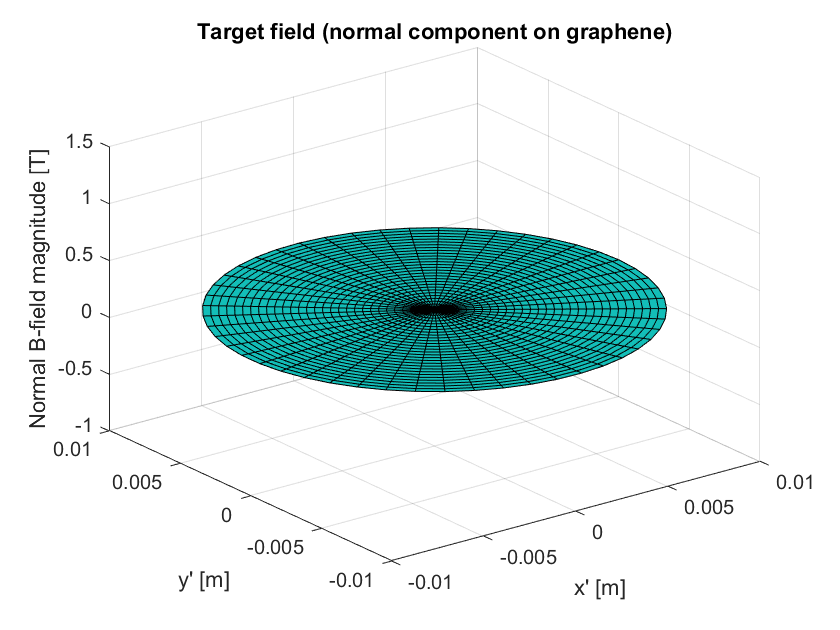

surf(Xl, Yl, B0n);
xlabel("x' [m]")
ylabel("y' [m]")
zlabel('Normal B-field magnitude [T]')
title('Target field (normal component on graphene)')

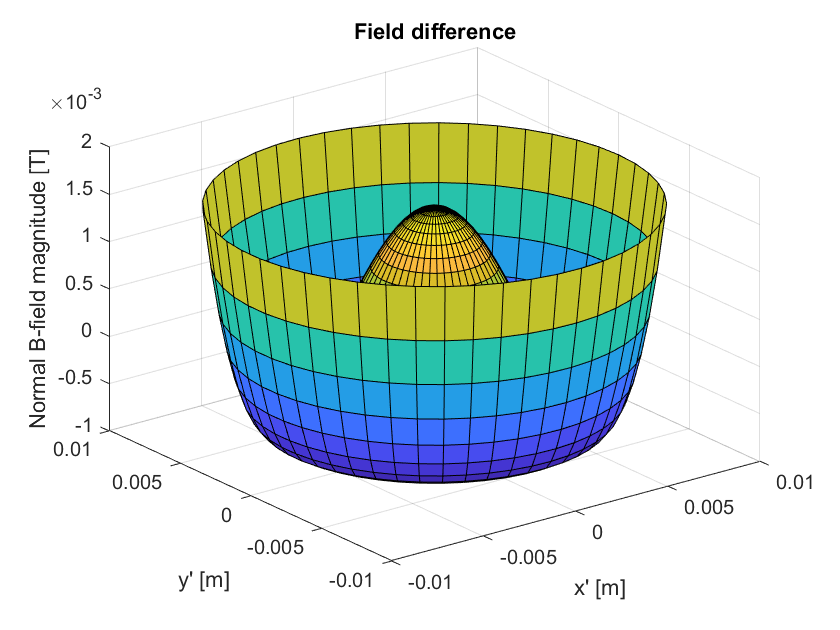

surf(Xl, Yl, Bn-B0n);
xlabel("x' [m]")
ylabel("y' [m]")
zlabel('Normal B-field magnitude [T]')
title('Field difference')

## Clean-up

Run this if you want to keep only simulation config

% clear p dV rV rh B B_0 dm rm maxB B0n B0 B_best B_fel b_field_at_edge b_field_at_origo B_func_from_x b_str_at_edge b_str_at_origo b_uniformity Bn Bx By Bz dipole_in_domain error f1 F1 f2 F2 get_Md get_Mr i inprod m n N nd nr R T x X Xl xx Y Yl Z